Test algorithm S

n_runs = 5000000;
n_toChoose = 5;
n_options = 200;
l_numbers = 1:n_options;
results = zeros(n_runs,n_toChoose);
counts = zeros(1,n_options);

parfor i=1:n_runs
    results(i,:) = randMfromN(l_numbers,n_options,n_toChoose);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 8 workers.


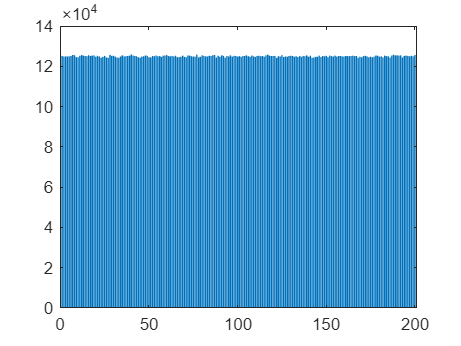


for i=1:n_options
    counts(i) = sum(results(:)==i);
end

Px = (counts/n_runs);
Qx = (n_toChoose/n_options);

bar(counts)

min_count = min(counts)

min_count = 124207

max_count = max(counts)

max_count = 125863

expected = n_toChoose/n_options*n_runs

expected = 125000

divergence = sum(Px.*log(Px/Qx)) % Kullback–Leibler (KL) divergence

divergence = 1.9171e-05